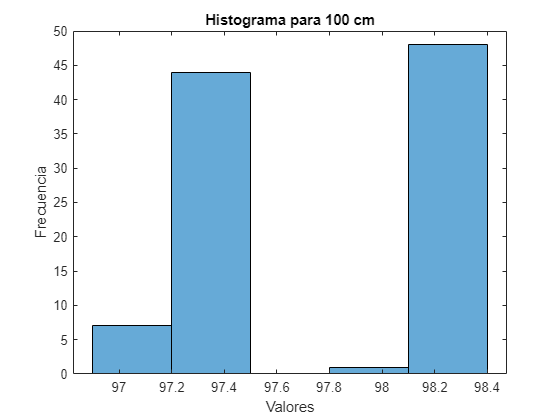

Número de elementos: 100
Valor mínimo: 96.92
Valor máximo: 98.32


% Define el nombre del archivo CSV
sample1 = 'C:\Users\Joho_\Desktop\semestre\fundamentos de robotica movil\labs\lab3\Sample1.csv';

% Lee los datos1del archivo CSV
datos1= readtable(sample1);

% Suponemos que las columnas son:
% Columna 1: Valores Reales
% Columna 2: Valores Predichos
% Columna 3: Distancia
datosNumericos1 = table2array(datos1);
valorReal1 = 100;
histogramaDeVector(datosNumericos1);

function histogramaDeVector(vectorDatos)
    % Esta función crea un histograma a partir de un vector de datos.

    % Verificar si el vectorDatos está vacío
    if isempty(vectorDatos)
        disp('El vector está vacío. Proporciona un vector con datos.');
        return;
    end

    % Crear el histograma
    figure; % Abre una nueva figura
    histogram(vectorDatos); % Crea el histograma
    title('Histograma para 100 cm'); % Título del histograma
    xlabel('Valores'); % Etiqueta del eje X
    ylabel('Frecuencia'); % Etiqueta del eje Y

    % Guardar la figura como una imagen
    saveas(gcf, 'C:\Users\Joho_\Desktop\semestre\fundamentos de robotica movil\labs\lab3\histograma100cm.png');

    % Mostrar información básica
    disp(['Número de elementos: ', num2str(length(vectorDatos))]);
    disp(['Valor mínimo: ', num2str(min(vectorDatos))]);
    disp(['Valor máximo: ', num2str(max(vectorDatos))]);
end
